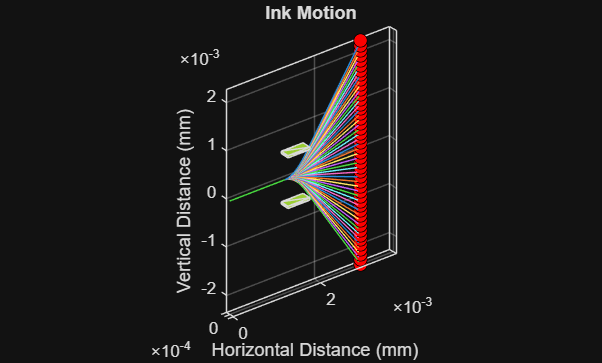

clear
%----Given Values-------
d = 84 * 10^-6;     %Diameter of droplet (m)
r = 42 * 10^-6;     %Radius of droplet (m)
D = 3 *10^-3;       %Distance to paper (m)
vx = 20;            %Velocity in x direction (m/s)
L1 = 0.5 * 10^-3;   %Length of Capacitor (m)
L2 = 1.25 * 10^-3;  %Distance between paper and cap (m)
q = -1.9*10^-10;    %Charge of electron (C)
pd = 1000;          %Density of droplet (kg/m^3)
W = 1 *10^-3;       %Diameter between Cap plates (m)
vy = 0;
Volt = 0;

%------Equations------
T = L1 / vx;        %Droplet time in capacitor
m = pd * (4/3)*pi*(r)^3;  %Mass of droplet
vf = sqrt(vx^2 + vy^2); %Velocity after exiting Cap
E = Volt/W;
ay = (q*E)/m;

%----Condition values----
dt = .000001;  %Time step
i = 1;
u = 1;
x(1) = 0;
z(1) = 0;
o = 1;

%The letter I at font 11 and 300 dpi will be 3.88mm tall

%Points is where the center of the droplet has to land on the paper
%Found by 3.88mm / 2 = 1.94mm --> 1.94mm - .042mm = 1.898mm
points(1) = 1.898*10^-3;
%Example: points(2) = points(1) - radius of droplet
while points(o) > -1.94*10^-3
    o = o + 1;
    points(o) = points(o-1) - d;
end

numDistPoints = floor((D/dt)/20);

%--------- Part 2: Varried Voltages ---------------------------------------

%Calculates the voltage for every location the droplet has to land on the
%paper
for it = 1:length(points)
    V(it) = (m*points(it)*W*(vx)^2)/(q*L1*L2);
end

j = zeros(length(points),numDistPoints);   %Initialize the array for plotting the z-axis

for test = 1:length(points)
    Vol = V(test);
    E = Vol / W;
    % ay = q*E/m;

    %Reset indexes
    x(1) = 0;
    z(1) = 0;
    vy = 0;

    for i = 2:numDistPoints      %iterations in mm
        % Update index

        beforeCap = x(i-1) < (D-L1-L2);
        afterCap = x(i-1) > (D-L2);

        % Calculate new velocities (only y changes)
        if ~beforeCap && ~afterCap
            ay = q*E/m;
            vy = vy + ay * dt;
        else
            ay = 0;
        end

        % Calculate new positions

        x(i) = x(i-1) + vx * dt;
        z(i) = z(i-1) + vy * dt + ay * dt^2;
        j(test,i) = z(i);
    
    end
end
y = zeros(size(x)); % Initialize z positions for 3D plot


%-------------Capacitor Display-------------------

InkMotionGraph(x,y,j,points);


%--------------- Part 3: Voltage graph -----------------------------


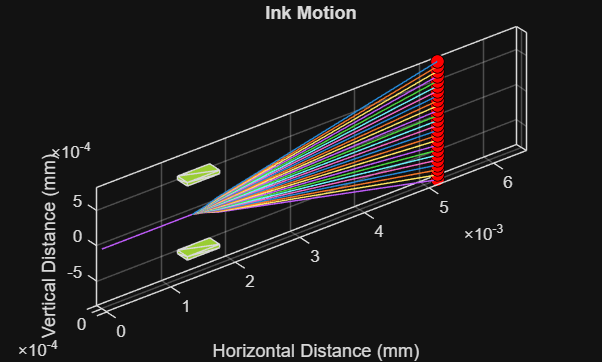

%--------------- Part 4: Adjusted Parameters -----------------------
%--------- Part 4a -------------

%----Given Values-------
d = 84 * 10^-6;     %Diameter of droplet (m)
r = 42 * 10^-6;     %Radius of droplet (m)
vx = 20;            %Velocity in x direction (m/s)
L1 = 0.5 * 10^-3;   %Length of Capacitor (m)
L2 = 3.75 * 10^-3;  %Distance between paper and cap (m)
D = 1.25 * 10^-3 + L1 + L2;  %Distance to paper (m)
q = -1.9*10^-10;    %Charge of electron (C)
pd = 1000;          %Density of droplet (kg/m^3)
W = 1 *10^-3;       %Diameter between Cap plates (m)
vy = 0;

%------Equations------
T = L1 / vx;        %Droplet time in capacitor
m = pd * (4/3)*pi*(r)^3;  %Mass of droplet
vf = sqrt(vx^2 + vy^2); %Velocity after exiting Cap

%----Condition values----
dt = .00001;  %Time step
i = 1;
u = 1;
x(1) = 0;
z(1) = 0;
o = 1;

% calculated max Voltage = 2613.389
CapTime = L1 / vx; % s

maxV = floor((W^2 * m) / (CapTime^2 * q)); % V

E = maxV / W;
ay = q*E/m;

peak = (ay * CapTime^2);

clear points
points(1) = peak;
while points(o) > -peak
    o = o + 1;
    points(o) = points(o-1) - d;
end

numDistPoints = floor((D/dt)/20);

clear V
for it = 1:length(points)
    V(it) = (m*points(it)*W*(vx)^2)/(q*L1*L2);
end

clear x
clear z
clear y
clear j
clear test

for test = 1:length(points)
    Vol = V(test);
    E = Vol / W;
    % ay = q*E/m;

    %Reset indexes
    x(1) = 0;
    z(1) = 0;
    vy = 0;

    for i = 2:numDistPoints      %iterations in mm
        % Update index

        beforeCap = x(i-1) < (D-L1-L2);
        afterCap = x(i-1) > (D-L2);

        % Calculate new velocities (only y changes)
        if ~beforeCap && ~afterCap
            ay = q*E/m;
            vy = vy + ay * dt;
        else
            ay = 0;
        end

        % Calculate new positions

        x(i) = x(i-1) + vx * dt;
        z(i) = z(i-1) + vy * dt + ay * dt^2;
        j(test,i) = z(i);
    
    end
end
y = zeros(size(x)); % Initialize z positions for 3D plot

%-------------Capacitor Display-------------------

InkMotionGraph(x,y,j,points);

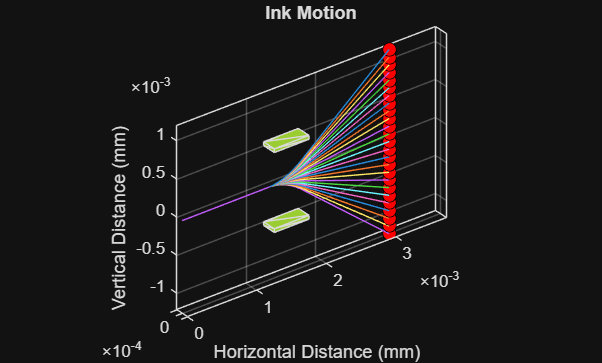

%--------- Part 4b -------------

%----Given Values-------
d = 84 * 10^-6;     %Diameter of droplet (m)
r = 42 * 10^-6;     %Radius of droplet (m)
vx = 20;            %Velocity in x direction (m/s)
L1 = 0.5 * 10^-3;   %Length of Capacitor (m)
L2 = 1.25 * 10^-3;  %Distance between paper and cap (m)
D = 1.25 * 10^-3 + L1 + L2;  %Distance to paper (m)
q = -1.9*10^-10;    %Charge of electron (C)
pd = 1000;          %Density of droplet (kg/m^3)
W = 1 *10^-3;       %Diameter between Cap plates (m)
vy = 0;

%------Equations------
m = pd * (4/3)*pi*(r)^3;  %Mass of droplet
vf = sqrt(vx^2 + vy^2); %Velocity after exiting Cap

%----Condition values----
dt = .000001;  %Time step
i = 1;
u = 1;
o = 1;

% Calculate max Voltage
CapTime = L1 / vx; % s

maxV = floor((W^2 * m) / (CapTime^2 * q)); % V

TotT = D / vx; % s
E = maxV / W;
ay = q*E/m;

peak = (ay * CapTime^2);

clear points
points(1) = peak;
while points(o) > -peak
    o = o + 1;
    points(o) = points(o-1) - d;
end

numDistPoints = floor((D/dt)/20);

clear V
for it = 1:length(points)
    V(it) = (m*points(it)*W*(vx)^2)/(q*L1*L2);
end

clear x
clear z
clear y
clear j
clear test

for test = 1:length(points)
    Vol = V(test);
    E = Vol / W;
    % ay = q*E/m;

    %Reset indexes
    x(1) = 0;
    z(1) = 0;
    vy = 0;

    for i = 2:numDistPoints      %iterations in mm
        % Update index

        beforeCap = x(i-1) < (D-L1-L2);
        afterCap = x(i-1) > (D-L2);

        % Calculate new velocities (only y changes)
        if ~beforeCap && ~afterCap
            ay = q*E/m;
            vy = vy + ay * dt;
        else
            ay = 0;
        end

        % Calculate new positions

        x(i) = x(i-1) + vx * dt;
        z(i) = z(i-1) + vy * dt + ay * dt^2;
        j(test,i) = z(i);
    
    end
end
y = zeros(size(x)); % Initialize z positions for 3D plot

%-------------Capacitor Display-------------------

InkMotionGraph(x,y,j,points);

%------------------- Functions -------------------------
function c = InkMotionGraph(x_, y_, j_, points_)
    width = .2*10^-3;
    height = .05*10^-3;
    Fa1 = 1.25*10^-3;     %First face
    point1 = 0.5*10^-3;
    point2 = 1.75*10^-3;
    
    % Define the vertices of the cuboid
    P = [Fa1, width/2, point1;               %V1
         point2, width/2, point1;
         point2, -width/2, point1;
         Fa1, -width/2, point1;           %V4
         Fa1, width/2, height+point1;          %V5
         point2, width/2, height+point1;
         point2, -width/2, height+point1;
         Fa1, -width/2, height+point1];     %V8
    
    Q = [Fa1, width/2, -point1;               %V1
         point2, width/2, -point1;
         point2, -width/2, -point1;
         Fa1, -width/2, -point1;           %V4
         Fa1, width/2, -height-point1;          %V5
         point2, width/2, -height-point1;
         point2, -width/2, -height-point1;
         Fa1, -width/2, -height-point1];     %V8
    
    % Create the alphaShape object
    alpha_radius = 3*10^-3;
    Tcap = alphaShape(P, alpha_radius);
    Bcap = alphaShape(Q, alpha_radius);
    
    %----------------------------------------------
    
    figure;
    plot3(x_,y_,j_)
    view(3);
    box on;
    grid on;
    title('Ink Motion');
    xlabel('Horizontal Distance (mm)');
    zlabel('Vertical Distance (mm)');
    hold on;
    
    plot(Tcap);
    plot(Bcap);
    xlim([0 (x_(end) + x_(end)/4)]); % Makes graph look nicer
    
    % Animate the projectile
    for l = 1:length(points_)
        h = plot3(x_(1), y_(1), j_(l,1), 'ko', 'MarkerSize', 8, 'MarkerFaceColor', 'r');
        for k = 1:length(x_)
    
            h.XData = x_(k);
            h.ZData = j_(l,k);
            %drawnow;
        
        end
    end
    hold off;
    c = true;
end